**Valentin Portillo Galvan**

**Antoine Joseph Nadheesh**

## **Exam MTS 101 B: Matlab Project**

## **I - Matlab Project**

## **Part I: Eigenvalues and eigenvectors**

(Please, find atached the hand part.)

For each matrix Ai, use eig to get a matrix D whose diagonal entries are the eigenvalues of Ai, and a matrix P whose columns are associated eigenvectors. Record P and D, and inspect D to be sure the eigenvalues produced by eig agree with what you calculated by hand in the previous question.

Calculate the product AP and PD for each Ai, to verify that AP = PD.

clear all; clc; close all;

A =[5 2 ; 4 3];
[P,D] = eig(A)

P =           0.71         -0.45
          0.71          0.89


D =           7.00             0
             0          1.00


A*P 

ans =           4.95         -0.45
          4.95          0.89


P*D 

ans =           4.95         -0.45
          4.95          0.89


% We can see that A*P = P*D 

A =[4 3 ; 3 4];
[P,D]=eig(A)

P =          -0.71          0.71
          0.71          0.71


D =           1.00             0
             0          7.00


A*P

ans =          -0.71          4.95
          0.71          4.95


P*D

ans =          -0.71          4.95
          0.71          4.95


% We can see that A*P = P*D 

A =[1 1 ; 1 1];
[P,D]=eig(A)

P =          -0.71          0.71
          0.71          0.71


D =              0             0
             0          2.00


A*P

ans =              0          1.41
             0          1.41


P*D

ans =              0          1.41
             0          1.41


% We can see that A*P = P*D 

A =[0 1 ; 1 0];
[P,D]=eig(A)

P =          -0.71          0.71
          0.71          0.71


D =          -1.00             0
             0          1.00


A*P

ans =           0.71          0.71
         -0.71          0.71


P*D

ans =           0.71          0.71
         -0.71          0.71


% We can see that A*P = P*D 

A =[25 0 20;0 1 0;20 0 41];
[P,D]=eig(A)

P =              0          0.83          0.56
         -1.00             0             0
             0         -0.56          0.83


D =           1.00             0             0
             0         11.46             0
             0             0         54.54


A*P

ans =              0          9.49         30.58
         -1.00             0             0
             0         -6.42         45.16


P*D

ans =              0          9.49         30.58
         -1.00             0             0
             0         -6.42         45.16


% We can see that A*P = P*D 

## **Part II: Matrix inverses and infinite series**

1) Use the up arrow key to execute the sum line repeatedly and watch to see that this series does seem to converge. (The first time you execute this line, you get S = I + C; the second time you get I + C + C2; etc.) How many times must you repeat it until the matrix S seems to stop changing, at least as far as what you see on the screen?

For the case of the matrix given, it never stop changing. With a little bit of research, we discovered that we need the norm to be inferior to one in order for the matrix S look like it's not changing, other wise, like in this case, since the norm was bigger to 1, it grew bigger each time (tryied 1000 times).

In order to to the tests, we just take the norm of C (6.74) and selected a bigger number, divided C by that number and that way we reduced the norm to inferior to 1. In our case we divided between 7 and then did the tests. We obtained that from the 37th iteration it stoped changing (or seemed at least in the screen). 

* For practical and waste purposes we don't print all the results (2 sheet for just the display of iterations)

2) One way to check whether S is close to the inverse of (I -􀀀 C) is to see whether the norm of (I 􀀀 C)S 􀀀 I is small. Experiment with different values of k to and how many terms of the series you must use in S = I +C +C2 + ... +Ck in order to get the norm of (I 􀀀-  C)S -􀀀 I to be 10􀀀^-10 or smaller.

We found that for k = 22, the norm gets very small (taking into account our C = C / 7 in order to let the norm be less than 1)

* For practical and waste purposes we don't print all the results  (2 sheet for just the display of iterations)

(Please, find atached the hand part.)

clear all; clc; close all;
C = [[1 -1 5]
    [0 1 -2]
    [1 3 -3]];
I = eye(3); S = I;
format long

for i = 1: 1000
    S = I + C*S;
end

first_norm = norm(C)

first_norm =    6.742121479436213


C1 = C / 7;
norm_C1 = norm(C1)

norm_C1 =    0.963160211348030



I = eye(3); S = I;
for i = 1: 40
    i;
    S = I + C1*S ;
end

for i = 1:24
    S = I;
    for j = 1:i
       S = S + mpower(C1, j);
    end
    i;
    norm = find_small_norm(S, C1, I);
end
inverse_to_find = inv((I - C1))

inverse_to_find =    1.269230769230769   0.096153846153846   0.615384615384615
  -0.038461538461538   1.057692307692308  -0.230769230769231
   0.115384615384615   0.326923076923077   0.692307692307692


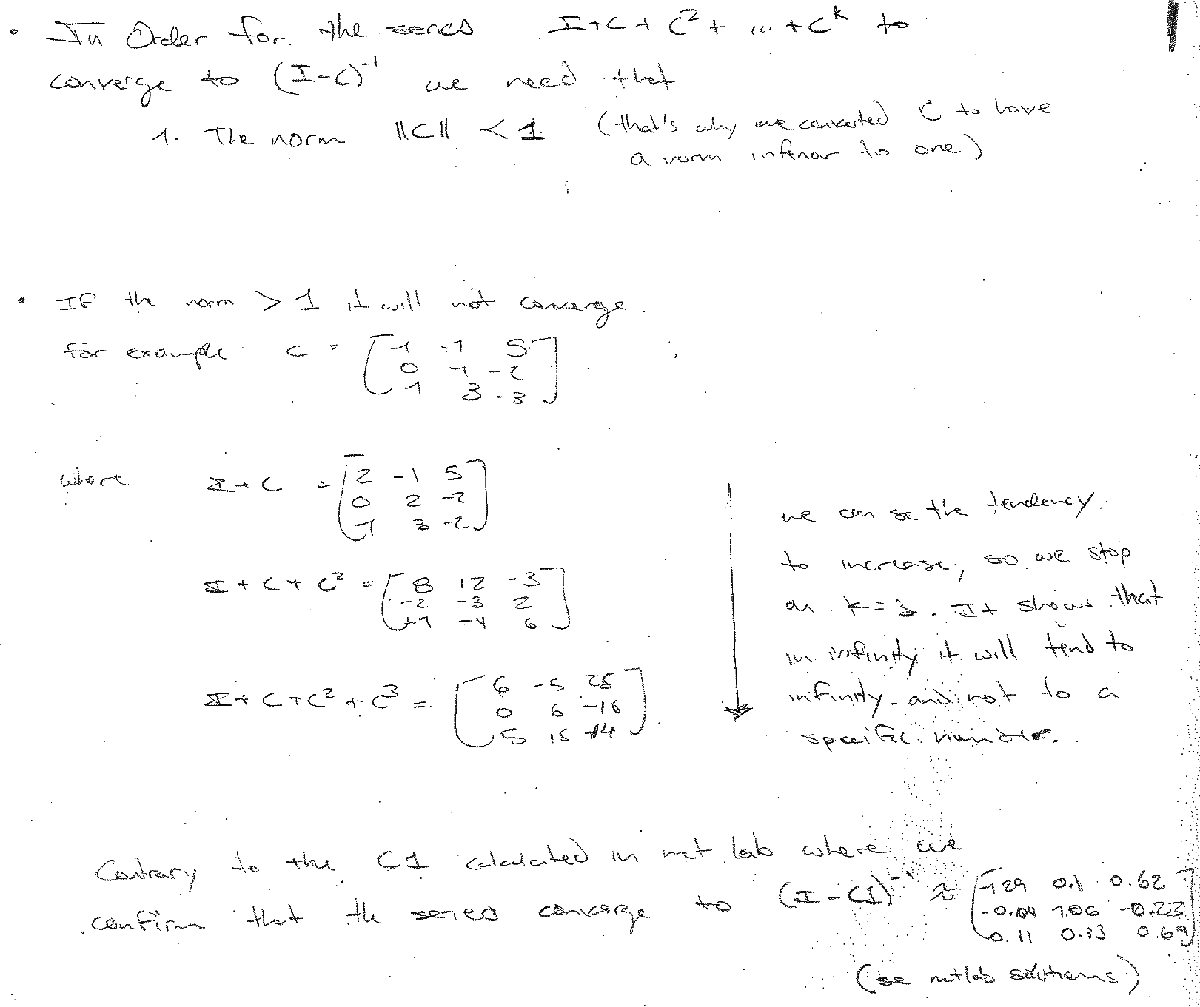

## **Part III: Fishing in George's Bank    **

1. If the haddock population in 1900 is x(1) = [100; 0; 0; 0; 0; 0; 0; 0; 0; 0]T (units are millions of pounds), what will the population be like in 1910? 1920? 1930? 1950? 1990? 2000? Based upon what you have seen, do you believe the population to be stable or unstable?

- In **1910** : 827.68, **1920** : 15950.25, **1930**: 286844.55, **1950**: 93 500 233,  **1990**: 9 930 419 617 092.07`,` **2000**: 179 269 447 526 362.06

- From what we have seen, it's stable in the sense of growth. the growth is continuous (which we can observe in Figure 2), exponential (observable in Figure 1) and positive. And this seems logical since there are no external factors affecting the haddock multiplication and it's a normal population growth graph.

2. Suppose pollution has the efect of lowering each birth rate by 10% of the value given above and each survival coeficient by 15% beginning in 1950. What efect does this have on the population in 1990 as compared to having no pollution efects?

-     It reduces the velocity with which the population grows starting from 1950 as we can observe in Figure 3. Specifically, about 1990, the reduction is obout 1 % lower with 40 years pollution.

3. Beginning in 1925, assume that fish 3 years old and older are caught at a rate such that each year, 25% of those groups are taken. Fish under 3 years old may not be taken (the distinction is based upon size).

(a)What is the matrix form of the model now? ( modification of equation (1), above). Did you assume the fish were harvested before or after the annual birth process occured? Please generalize to show a model reecting any harvesting rate which you may denote by h. Thus above, h = 0:20. 

- The matrix form the model now would be: 

`     0`     `0`  `1``.``50`  `4``.``20`  `3``.``80`  `2``.``50`  `1``.``50`     `0`     `0`     `0`

  `0``.``65`     `0`     `0`     `0`     `0`     `0`     `0`     `0`     `0`     `0`

     `0`  `0``.``68`     `0`     `0`     `0`     `0`     `0`     `0`     `0`     `0`

     `0`     `0`  `0``.``56`     `0`     `0`     `0`     `0`     `0`     `0`     `0`

     `0`     `0`     `0`  `0``.``52`     `0`     `0`     `0`     `0`     `0`     `0`

     `0`     `0`     `0`     `0`  `0``.``45`     `0`     `0`     `0`     `0`     `0`

     `0`     `0`     `0`     `0`     `0`  `0``.``41`     `0`     `0`     `0`     `0`

     `0`     `0`     `0`     `0`     `0`     `0`  `0``.``30`     `0`     `0`     `0`

     `0`     `0`     `0`     `0`     `0`     `0`     `0`  `0``.``26`     `0`     `0`

     `0`     `0`     `0`     `0`     `0`     `0`     `0`     `0`  `0``.``15`     `0`

- We assumed that the fish were harvested after the annual birth and we can see it wit the results (see code):

-  On Code --> We can see that after the third year the affectation of the harvesting takes place and that the third year births is the same as the model without harvesting, so we're assuming that the harvesting takes place after the annual birth process

- To generalize we're goig to do a multiplication to the main matrix from the third row. The new matrix would be:

        `0`        `0`     `1``.``50`     `4``.``20`     `3``.``80`     `2``.``50`     `1``.``50`        `0`        `0`        `0`

     `0``.``65`        `0`        `0`        `0`        `0`        `0`        `0`        `0`        `0`        `0`

        `0`     `0``.``68`        `0`        `0`        `0`        `0`        `0`        `0`        `0`        `0`

        `0`        `0`     `0``.``75*(1-h) ` `0`        `0`        `0`        `0`        `0`        `0`        `0`

        `0`        `0`        `0`     `0``.``70*(1-h)  ``0`        `0`        `0`        `0`        `0`        `0`

        `0`        `0`        `0`        `0`     `0``.``60*(1-h)  ``0`        `0`        `0`        `0`        `0`

        `0`        `0`        `0`        `0`        `0`     `0``.``55*(1-h)  ``0`        `0`        `0`        `0`

        `0`        `0`        `0`        `0`        `0`        `0`     `0``.``40*(1-h)  ``0`        `0`        `0`

        `0`        `0`        `0`        `0`        `0`        `0`        `0`     `0``.``35*(1-h)  ``0`        `0`

        `0`        `0`        `0`        `0`        `0`        `0`        `0`        `0`     `0``.``20*(1-h)  ``0`

(b) What does the population now look like for 1930, 1950, 1995, 2000? Is this a good strategy?

- **1930: **25525.26, **1950:** 545 917.56, **1995:** 547 536 267.75, **2000:** 1 180 011 294.95

- Yes, sicne the population continue growing, so there should be no problems regarding the population of haddock. But as the population grows that fast I would say that maybe they could even do a more aggressive harvesting.

% ------ PART III, Question 1 ------
clear all; clc; close all;
A = [[0 0 1.5 4.2 3.8 2.5 1.5 0 0 0]
    [0.65 0 0 0 0 0 0 0 0 0]
    [0 0.68 0 0 0 0 0 0 0 0]
    [0 0 0.75 0 0 0 0 0 0 0]
    [0 0 0 0.7 0 0 0 0 0 0]
    [0 0 0 0 0.6 0 0 0 0 0]
    [0 0 0 0 0 0.55 0 0 0 0]
    [0 0 0 0 0 0 0.4 0 0 0]
    [0 0 0 0 0 0 0 0.35 0 0]
    [0 0 0 0 0 0 0 0 0.2 0]];
x1 = transpose([100 0 0 0 0 0 0 0 0 0]);

% Population in 1910? 1920? 1930? 1950? 1990? 2000?
haddock1910 = population_haddock_in_time(x1, A, 1910 - 1900) ;
haddock1920 = population_haddock_in_time(x1, A, 1920 - 1900) ;
haddock1930 = population_haddock_in_time(x1, A, 1930 - 1900) ;
haddock1950 = population_haddock_in_time(x1, A, 1950 - 1900) ;
haddock1990 = population_haddock_in_time(x1, A, 1990 - 1900) ;
haddock2000 = population_haddock_in_time(x1, A, 2000 - 1900) ; 

format bank
haddock1910_sum = sum(haddock1910)

haddock1910_sum =         827.68


haddock1920_sum = sum(haddock1920)

haddock1920_sum =       15950.25


haddock1930_sum = sum(haddock1930)

haddock1930_sum =      286844.55


haddock1950_sum = sum(haddock1950)

haddock1950_sum =    93500233.00


haddock1990_sum = sum(haddock1990)

haddock1990_sum =  9930419617092.07


haddock2000_sum = sum(haddock2000)

haddock2000_sum =  179269447526362.06



%To see the evolution
years = (1901:1:2000);
x_k_1 = zeros(length(x1), length(years));
x_k_1_sums = zeros(1, length(years));

for i = 1:length(years)
    result = population_haddock_in_time(x1, A, years(i) - 1900);
    x_k_1(:,i) = result;
    x_k_1_sums(i) = sum(result);
end
x_k_1

x_k_1 =              0             0         66.30        139.23         88.18         78.76        196.11        310.78        320.84        373.51        595.22        855.88       1045.69       1328.29       1872.91       2576.66       3341.37       4379.48       5949.54       8036.78      10632.34      14100.48      18932.72      25393.28      33812.70      45040.77      60253.42      80596.87     107540.64     143487.45     191729.21     256206.78     342076.83     456697.05     610025.42     814875.57    1088202.09    1453148.19    1940809.30    2592200.95    3461883.14    4623248.74    6174565.98    8246536.75   11013433.38   14708551.32   19643784.07   26235115.63   35037746.82   46793733.51   62494512.89   83463604.26  111468167.04  148868878.21  198818979.92  265529138.30  354622294.89  473608648.48  632518880.83  844748686.99 1128187796.89 1506729079.92 2012282880.78 2687465861.73 3589193142.75 4793477187.69 6401835770.76 8549848428.11 11418584933.11 15249870075.63 203666691

x_k_1_sums

x_k_1_sums =          65.00         44.20         99.45        205.53        221.91        227.26        350.88        544.90        680.77        827.68       1151.04       1624.01       2125.32       2745.79       3708.70       5051.46       6707.29       8853.40      11860.27      15950.25      21269.00      28288.66      37809.78      50619.22      67578.18      90123.18     120383.08     160911.39     214886.30     286844.55     383099.98     511791.13     683508.51     912690.56    1218923.88    1628072.94    2174350.90    2903742.95    3878020.47    5179391.29    6917261.67    9238032.64   12337641.21   16477487.26   22006234.20   29389805.61   39250932.04   52421025.16   70009953.25   93500233.00  124872351.48  166771068.89  222727969.01  297459816.94  397266606.52  530561962.86  708581895.35  946332630.28 1263856124.56 1687918856.73 2254267561.58 3010643245.89 4020806244.74 5369910322.17 7171680148.24 9577998598.48 12791710744.94 17083722346.10 22815835481.59 30471247949.97 40

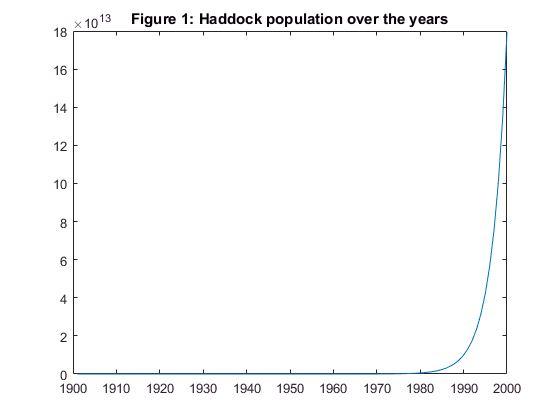


plot(years, x_k_1_sums)
title("Figure 1: Haddock population over the years")

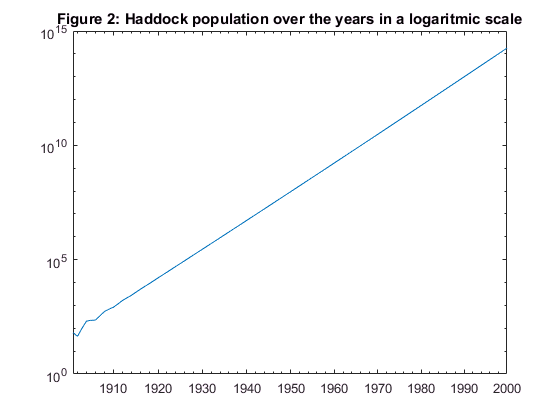

loglog(years, x_k_1_sums)
title("Figure 2: Haddock population over the years in a logaritmic scale")



% ------ PART III, Question 2 ------

A1 = A;
birth_rate_affectation = 0.10;
A1(1,:) = A1(1,:) * (1 - birth_rate_affectation); % first line is the birth rate info
affectation_survival = 0.15;
with_pollution_haddock_1990 = population_affectation_in_time_survival(x1, A, 1990 - 1900, 1900, 1950, affectation_survival)

with_pollution_haddock_1990 =  39253654644.08
 18358704393.46
 8982581738.08
 4847426950.09
 2441491926.16
 1054034581.80
  417129364.61
  120054952.68
   30233543.03
    4350772.99


with_pollution_haddock_1990_sum = sum(with_pollution_haddock_1990)

with_pollution_haddock_1990_sum =  75509662866.98


haddock1990_sum

haddock1990_sum =  9930419617092.07


% taking as pivot the "without pollution population in 1990: 
ratio_reduction = with_pollution_haddock_1990_sum / haddock1990_sum

ratio_reduction =           0.01


inverse_ratio_reduction = haddock1990_sum / with_pollution_haddock_1990_sum

inverse_ratio_reduction =         131.51


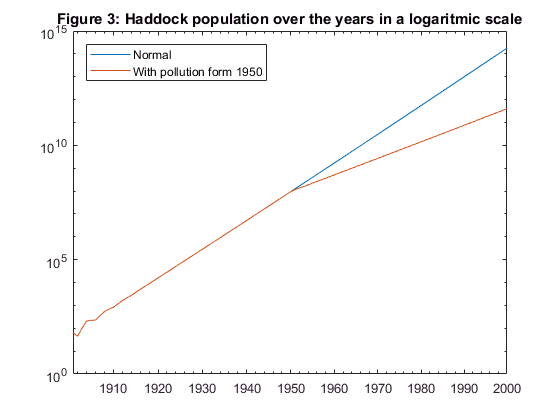


x_k_1_poll = zeros(length(x1), length(years));
x_k_1_poll_sums = zeros(1, length(years));

for i = 1:length(years)
    result = population_affectation_in_time_survival(x1, A, years(i) - 1900, 1900, 1950, affectation_survival);
    x_k_1_poll(:,i) = result;
    x_k_1_poll_sums(i) = sum(result);
end

figure;  
loglog(years, x_k_1_sums)
hold on;
loglog(years, x_k_1_poll_sums)
legend("Normal", "With pollution form 1950")
legend('Location','northwest')
title("Figure 3: Haddock population over the years in a logaritmic scale")
hold off;


% ------ PART III, Question 3 ------

A2 = A;
h = 0.25;
A2(4:end,:) = A(4:end,:) * (1 - h);
A2

A2 =              0             0          1.50          4.20          3.80          2.50          1.50             0             0             0
          0.65             0             0             0             0             0             0             0             0             0
             0          0.68             0             0             0             0             0             0             0             0
             0             0          0.56             0             0             0             0             0             0             0
             0             0             0          0.52             0             0             0             0             0             0
             0             0             0             0          0.45             0             0             0             0             0
             0             0             0             0             0          0.41             0             0             0             0
        

x_k_1_harvest = zeros(length(x1), length(years));
x_k_1_harvest_sums = zeros(1, length(years));

for i = 1:length(years)
    result = population_with_harvesting(x1, A, years(i) - 1900, 1900, 1925, h);
    x_k_1_harvest(:,i) = result;
    x_k_1_harvest_sums(i) = sum(result);
end
% We can see that after the third year the affectation of the harvesting takes place
% And that the third year births is the same as the model without harvesting, so
% we're assuming that the harvesting takes place after the annual birth process
x_k_1

x_k_1 =              0             0         66.30        139.23         88.18         78.76        196.11        310.78        320.84        373.51        595.22        855.88       1045.69       1328.29       1872.91       2576.66       3341.37       4379.48       5949.54       8036.78      10632.34      14100.48      18932.72      25393.28      33812.70      45040.77      60253.42      80596.87     107540.64     143487.45     191729.21     256206.78     342076.83     456697.05     610025.42     814875.57    1088202.09    1453148.19    1940809.30    2592200.95    3461883.14    4623248.74    6174565.98    8246536.75   11013433.38   14708551.32   19643784.07   26235115.63   35037746.82   46793733.51   62494512.89   83463604.26  111468167.04  148868878.21  198818979.92  265529138.30  354622294.89  473608648.48  632518880.83  844748686.99 1128187796.89 1506729079.92 2012282880.78 2687465861.73 3589193142.75 4793477187.69 6401835770.76 8549848428.11 11418584933.11 15249870075.63 203666691

x_k_1_harvest

x_k_1_harvest =              0             0         66.30        139.23         88.18         78.76        196.11        310.78        320.84        373.51        595.22        855.88       1045.69       1328.29       1872.91       2576.66       3341.37       4379.48       5949.54       8036.78      10632.34      14100.48      18932.72      25393.28      33812.70      45040.77      49399.00      61772.61      81228.78     100972.51     120767.53     150704.29     191296.45     236663.22     290281.51     361879.65     452818.36     560989.86     693999.95     863789.05    1075502.73    1334212.49    1655284.91    2058112.44    2558393.43    3176193.73    3944121.76    4901389.28    6089752.15    7562975.66    9394070.54   11671357.91   14499053.60   18009361.12   22371301.66   27791823.97   34523886.86   42884916.30   53272702.72   66178095.47   82207966.45  102119516.27  126855673.07  157584462.53  195755033.81  243170784.32  302073275.92  375243921.53  466136943.31  579046224.80  71


haddock1930_harvest = population_with_harvesting(x1, A2, 1930 - 1900, 1900, 1925, h);
haddock1950_harvest = population_with_harvesting(x1, A2, 1950 - 1900, 1900, 1925, h);
haddock1995_harvest = population_with_harvesting(x1, A2, 1995 - 1900, 1900, 1925, h);
haddock2000_harvest = population_with_harvesting(x1, A2, 2000 - 1900, 1900, 1925, h);


haddock1930_harvest_sum = sum(haddock1930_harvest)

haddock1930_harvest_sum =       25525.26


haddock1950_harvest_sum = sum(haddock1950_harvest)

haddock1950_harvest_sum =      545917.56


haddock1995_harvest_sum = sum(haddock1995_harvest)

haddock1995_harvest_sum =   547536267.75


haddock2000_harvest_sum = sum(haddock2000_harvest)

haddock2000_harvest_sum =  1180011294.95


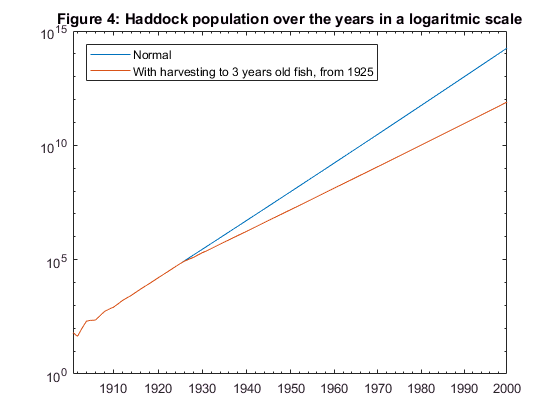


%lets compare with the graphs
figure;  
loglog(years, x_k_1_sums)
hold on;
loglog(years, x_k_1_harvest_sums)
legend("Normal", "With harvesting to 3 years old fish, from 1925")
legend('Location','northwest')
title("Figure 4: Haddock population over the years in a logaritmic scale")
hold off;

function n = find_small_norm(S, C, I)
    n = norm((I - C) * S - I);
end

function [R] = population_haddock_in_time(x1, A, k)
    R = mpower(A, k) * x1;
end

function [R] = population_affectation_in_time_survival(x1, A, k, start_date, from_date_survival, affectation_survival)
    
    if (start_date + k < from_date_survival)
        R = population_haddock_in_time(x1, A, k);
    else
        diff_from_start = from_date_survival - start_date;
        A1 = mpower(A, diff_from_start); % get the A powered until the date of affectation ("the normal part")
        A2 = A;
        A2(2:end,:) = A(2:end,:) * (1 - affectation_survival);
        diff_from_k = k - (from_date_survival - start_date);
        A2 = mpower(A2, diff_from_k); % get the A powered from the date of affectation
        R = (A2 * A1) * x1;
    end  
end

function [R] = population_with_harvesting(x1, A, k, start_date, from_date_harvest, h)
    
    if (start_date + k < from_date_harvest)
        R = population_haddock_in_time(x1, A, k);
    else
        diff_from_start = from_date_harvest - start_date;
        A1 = mpower(A, diff_from_start); % get the A powered until the date of affectation ("the normal part")
        A2 = A;
        A2(4:end,:) = A(4:end,:) * (1 - h);
        diff_from_k = k - (from_date_harvest - start_date);
        A2 = mpower(A2, diff_from_k); % get the A powered from the date of affectation
        R = (A2 * A1) * x1;
    end  
end